## **Q2 - Perona Malik**

Write the function implementing nonlinear Perona-Malik diffusion (use as input Parrot image). 

Use the diffusion coefficient c(s) = 1/(1 + (s/k)2), where s = |∇u|.

### 2.1 - 1D Denoising

A a step with noise. Add noise, std=0.1 (where the step is between [0,1]). 

Compare denoising with linear diffusion and with P-M. Choose appropriate threshold k for P-M.

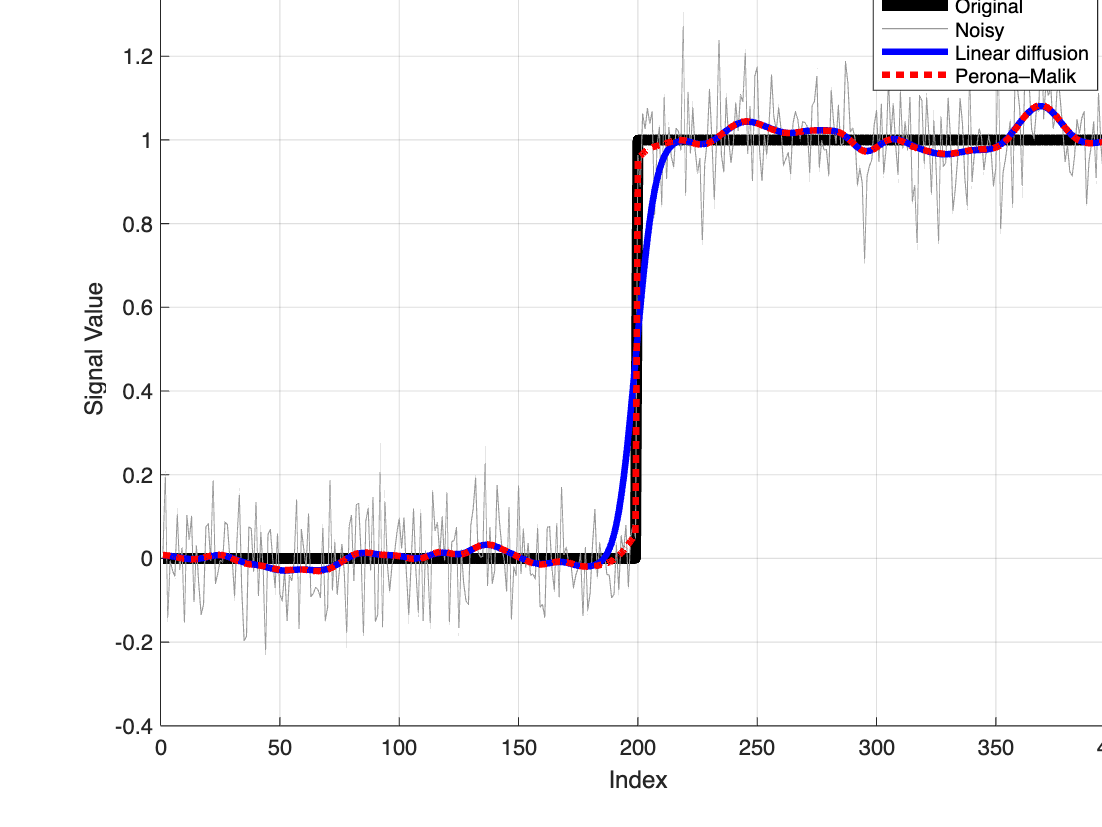

clear; close all; clc;

%% 1) Create 1D step function
N = 400;
u0 = zeros(1,N);
u0(N/2:end) = 1;      % step between 0 and 1

%% 2) Add Gaussian noise σ = 0.1
noise_std = 0.1;
u_noisy = u0 + noise_std*randn(size(u0));
lambda = 1;     % fidelity weight
%% Parameters for diffusion
dx = 1;
dt = 0.1;             % stable step size for 1D diffusion
num_iter = 200;

u_linear = u_noisy;

for it = 1:num_iter
    ux = [diff(u_linear), 0];   % forward difference
    ux_prev = [0, diff(u_linear)]; % backward difference
    lap = ux - ux_prev;         % 2nd derivative approximation
    u_linear = u_linear + dt * lap;
end


k = 0.09;      % threshold parameter — adjust for stronger/weaker edge preservation
u_PM = u_noisy;

for it = 1:num_iter
    % gradient (forward/backward)
    ux_fwd  = [diff(u_PM), 0];
    ux_back = [0, diff(u_PM)];

    % diffusion coefficients
    c_fwd  = 1 ./ (1 + (abs(ux_fwd)/k).^2);
    c_back = 1 ./ (1 + (abs(ux_back)/k).^2);

    % divergence of c · grad u
    div_term = c_fwd .* ux_fwd - c_back .* ux_back;
    fidelity = u_PM - u_noisy;
    % update
    u_PM = u_PM + dt * (div_term);% - lambda*fidelity);
end

%% ------------------------------------------------------------
% 5) Plot results
% ------------------------------------------------------------

figure; hold on;
plot(u0, 'k', 'LineWidth', 5);            % original step
plot(u_noisy, 'Color', [0.6 0.6 0.6]);    % noisy input
plot(u_linear, 'b', 'LineWidth', 3);    % linear diffusion
plot(u_PM, 'r', 'LineWidth',3,"LineStyle",":");        % PM diffusion
legend('Original','Noisy','Linear diffusion','Perona–Malik');
title('1D Denoising: Linear vs Perona–Malik');
xlabel('Index'); ylabel('Signal Value');
grid on;

Q1

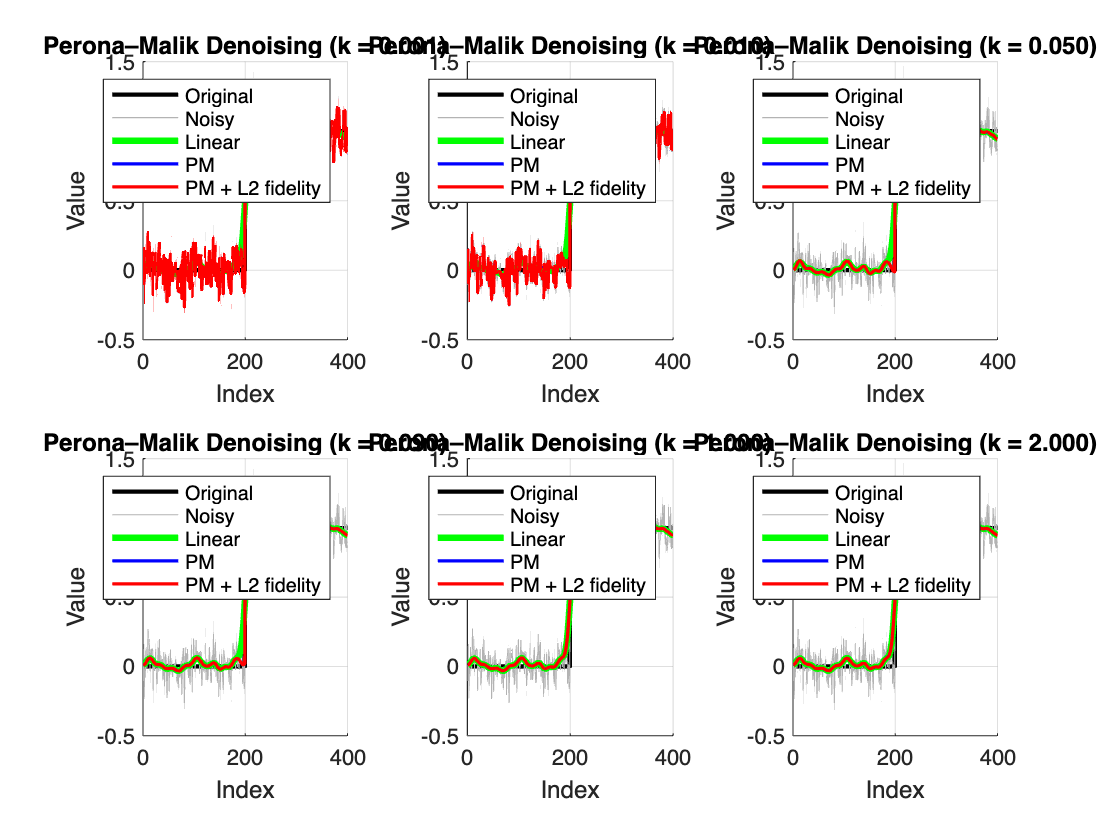

%% ------------------------------------------------------------
%  Perona–Malik + L2 fidelity: sweep over 5 k values
% -------------------------------------------------------------

clear; close all; clc;

%% 1) Create 1D step signal
N = 400;
u0 = zeros(1,N);
u0(N/2:end) = 1;

%% 2) Add Gaussian noise
noise_std = 0.1;
u_noisy = u0 + noise_std*randn(size(u0));

%% Numerical parameters
dt = 0.1;
num_iter = 200;

%% Fidelity parameter
lambda = 0.001;      % can adjust

%% k values to try
k_values = [0.001 0.01 0.05 0.09 1,2];

u_linear = u_noisy;

for it = 1:num_iter
    ux = [diff(u_linear), 0];
    ux_prev = [0, diff(u_linear)];
    lap = ux - ux_prev;        % discrete 2nd derivative
    u_linear = u_linear + dt * lap;
end

%% ------------------------------------------------------------
%  LOOP OVER 5 k VALUES
% ------------------------------------------------------------
figure;
tiledlayout(2,3);
for idx = 1:length(k_values)

    k = k_values(idx);
    u_PM = u_noisy;       % PM only
    u_PM_fid = u_noisy;   % PM + L2

    %% Run the diffusion
    for it = 1:num_iter
        
        % ----- PM only -----
        ux_fwd  = [diff(u_PM), 0];
        ux_back = [0, diff(u_PM)];
        c_fwd  = 1 ./ (1 + (abs(ux_fwd)/k).^2);
        c_back = 1 ./ (1 + (abs(ux_back)/k).^2);
        div_PM = c_fwd .* ux_fwd - c_back .* ux_back;
        u_PM = u_PM + dt * div_PM;

        % ----- PM + Fidelity -----
        ux_fwd  = [diff(u_PM_fid), 0];
        ux_back = [0, diff(u_PM_fid)];
        c_fwd  = 1 ./ (1 + (abs(ux_fwd)/k).^2);
        c_back = 1 ./ (1 + (abs(ux_back)/k).^2);
        div_PM_fid = c_fwd .* ux_fwd - c_back .* ux_back;
        fidelity = -lambda * (u_PM_fid - u_noisy);
        u_PM_fid = u_PM_fid + dt * (div_PM_fid + fidelity);

    end

    %% ------------------------------------------------------------
    %  PLOT FOR THIS k
    %% ------------------------------------------------------------
    nexttile;
    hold on;
    plot(u0, 'k', 'LineWidth', 2);
    plot(u_noisy, 'Color', [0.7 0.7 0.7]);
    plot(u_linear,  'g', 'LineWidth', 3);
    plot(u_PM, 'b', 'LineWidth',1.5);
    plot(u_PM_fid, 'r', 'LineWidth', 1.5);
    title(sprintf('Perona–Malik Denoising (k = %.3f)', k));
    legend('Original', 'Noisy','Linear', 'PM', 'PM + L2 fidelity');
    xlabel('Index'); ylabel('Value');
    grid on;

end

Q2

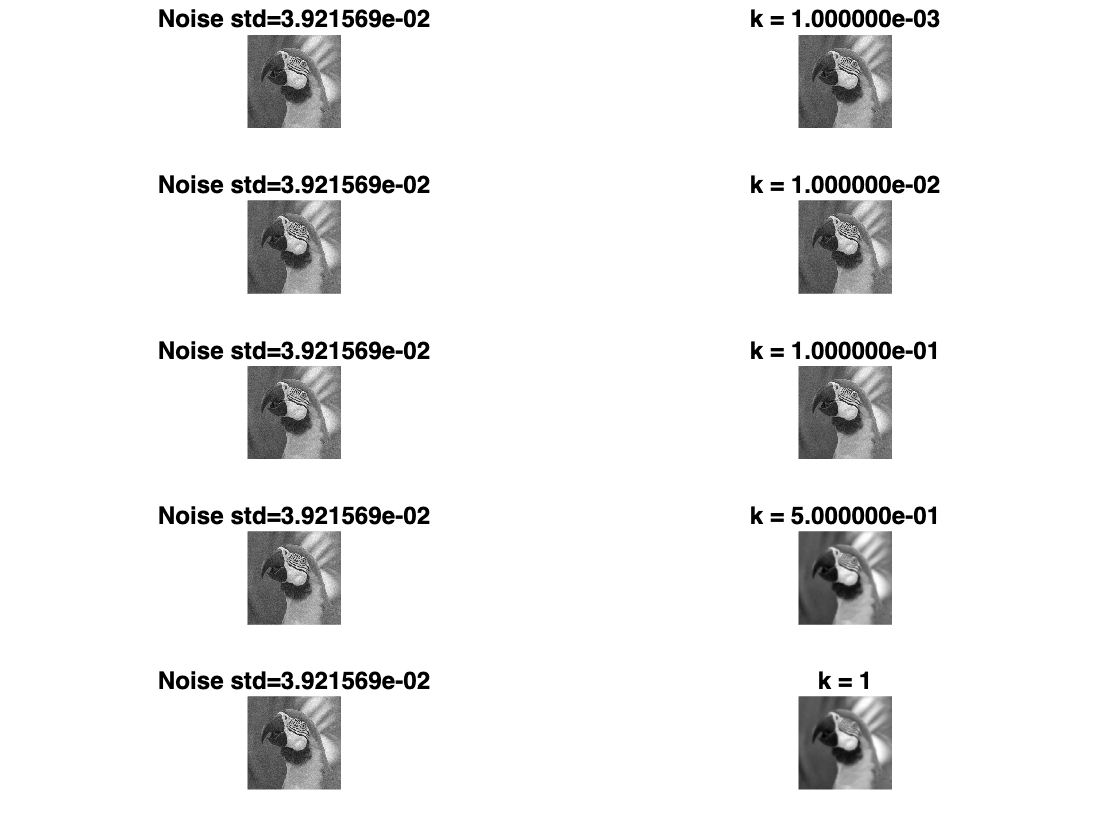

%% 2D Perona–Malik experiments using student's diffusionPM()

clear; close all; clc;
I = im2double(imread('Ex1/parrot.png'));
I = im2gray(I);

noise_levels = [10];
k_values = [0.001, 0.01 0.1 0.5 1];
dt = 0.2;
lambda = 0.1;   % no fidelity term in (b)

T = 5;
iter = round(T/dt);
figure;
tiledlayout(5,2,"TileSpacing","tight","Padding","tight");

for ni = 1:length(noise_levels)
    sigma = noise_levels(ni)/255; %0-1

    f = I + sigma * randn(size(I));

    for ki = 1:length(k_values)
        kpm = k_values(ki);

        [u,~,~] = diffusionPM(f,f,iter,dt,lambda,kpm);

       %nexttile; imshow(I,[]); title('Original');
       nexttile; imshow(f,[]); title(sprintf('Noise std=%d',sigma));
       nexttile; imshow(u,[]); title(sprintf('k = %d',kpm));

        %sgtitle(sprintf('std=%d, k=%d',sigma,kpm));
    end
end

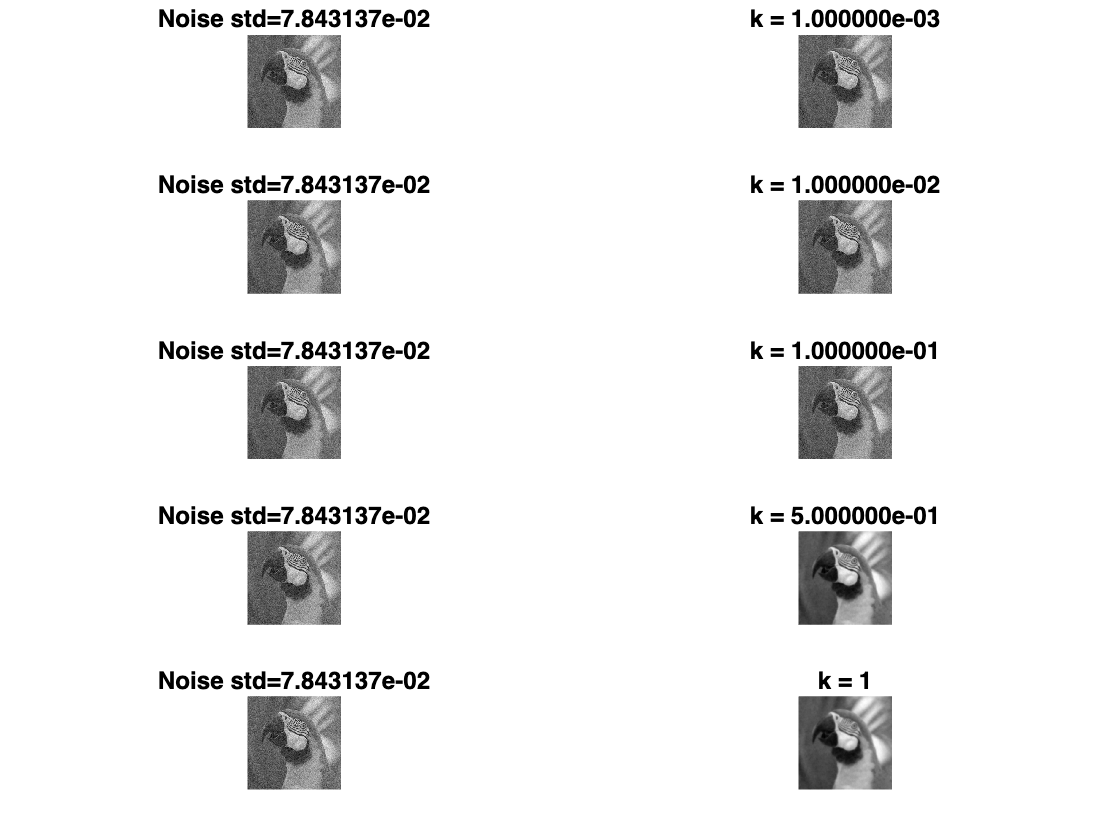




noise_levels = [20];
figure;
tiledlayout(5,2,"TileSpacing","tight","Padding","tight");

for ni = 1:length(noise_levels)
    sigma = noise_levels(ni)/255; %0-1

    f = I + sigma * randn(size(I));

    for ki = 1:length(k_values)
        kpm = k_values(ki);

        [u,~,~] = diffusionPM(f,f,iter,dt,lambda,kpm);

       %nexttile; imshow(I,[]); title('Original');
       nexttile; imshow(f,[]); title(sprintf('Noise std=%d',sigma));
       nexttile; imshow(u,[]); title(sprintf('k = %d',kpm));

        %sgtitle(sprintf('std=%d, k=%d',sigma,kpm));
    end
end

Q2b

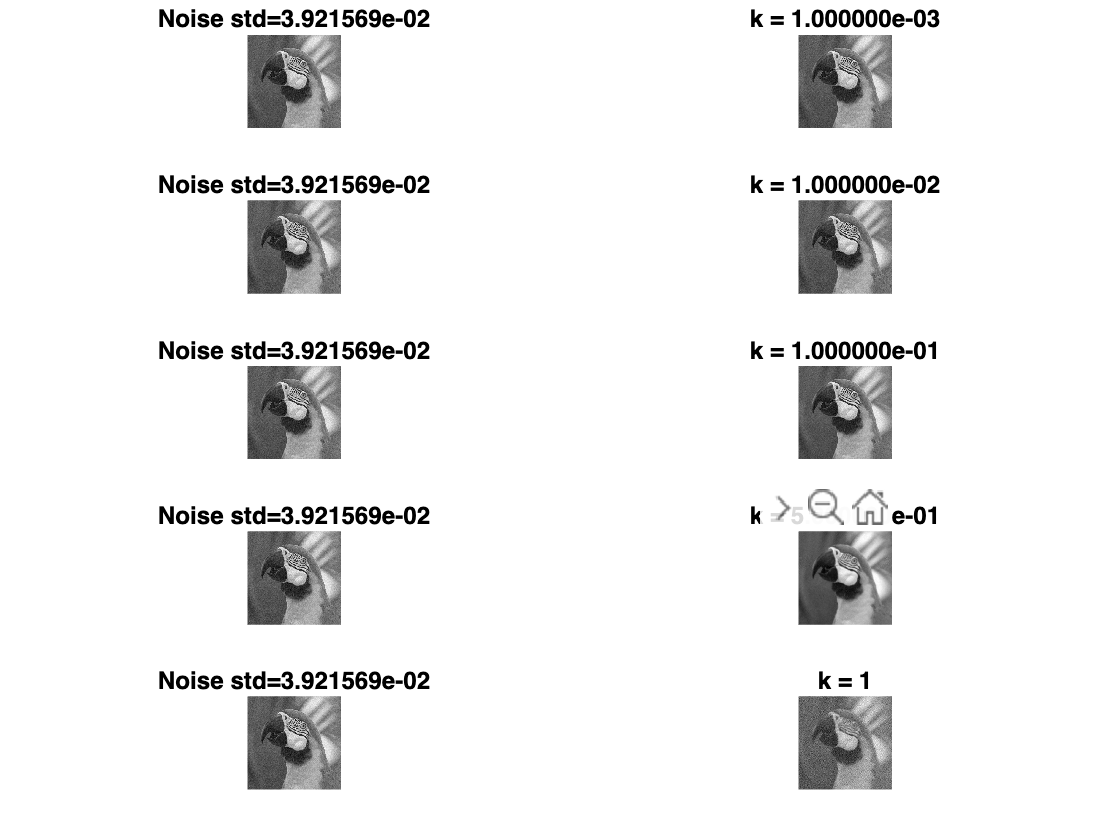


clear; close all; clc;
I = im2double(imread('Ex1/parrot.png'));
I = im2gray(I);

noise_levels = [10];
k_values = [0.001, 0.01 0.1 0.5 1];
dt = 1;
lambda = 0.1;   % no fidelity term in (b)

T = 5;
iter = round(T/dt);
figure;
tiledlayout(5,2,"TileSpacing","tight","Padding","tight");

for ni = 1:length(noise_levels)
    sigma = noise_levels(ni)/255; %0-1

    f = I + sigma * randn(size(I));

    for ki = 1:length(k_values)
        kpm = k_values(ki);

        [u,~,~] = diffusionPM(f,f,iter,dt,lambda,kpm);

       %nexttile; imshow(I,[]); title('Original');
       nexttile; imshow(f,[]); title(sprintf('Noise std=%d',sigma));
       nexttile; imshow(u,[]); title(sprintf('k = %d',kpm));

        %sgtitle(sprintf('std=%d, k=%d',sigma,kpm));
    end
end

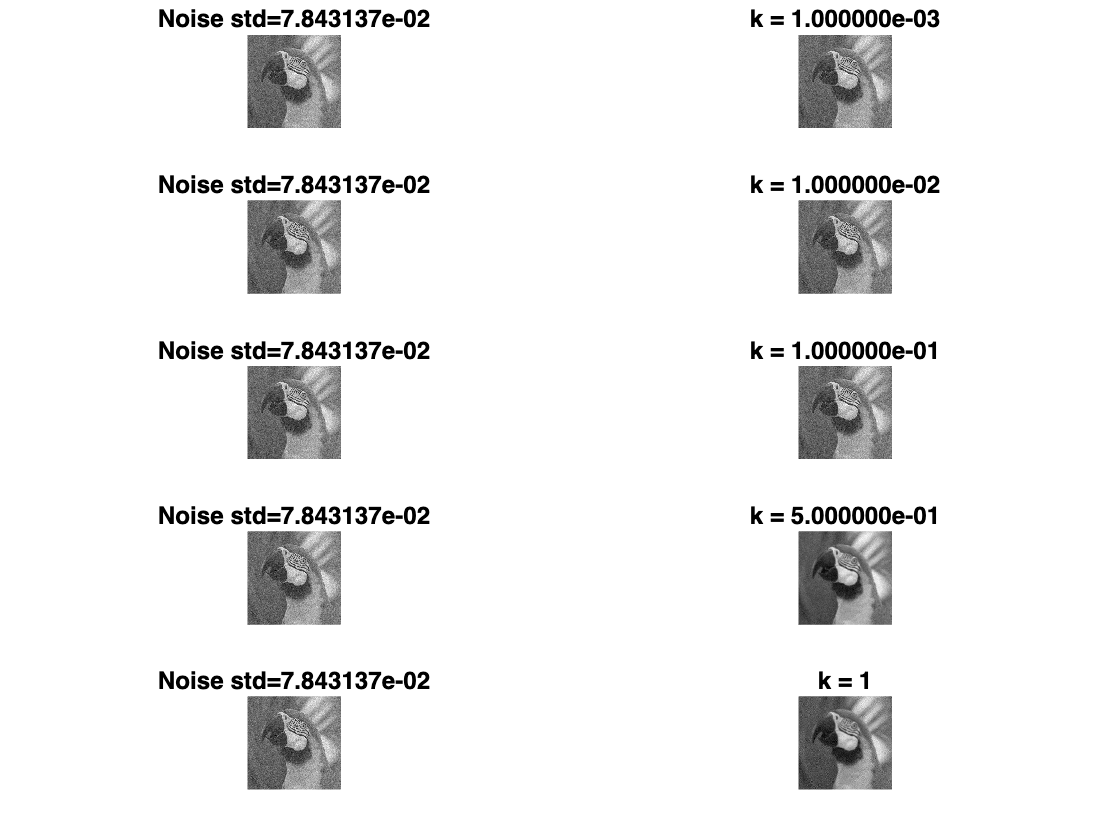




noise_levels = [20];
figure;
tiledlayout(5,2,"TileSpacing","tight","Padding","tight");

for ni = 1:length(noise_levels)
    sigma = noise_levels(ni)/255; %0-1

    f = I + sigma * randn(size(I));

    for ki = 1:length(k_values)
        kpm = k_values(ki);

        [u,~,~] = diffusionPM(f,f,iter,dt,lambda,kpm);

       %nexttile; imshow(I,[]); title('Original');
       nexttile; imshow(f,[]); title(sprintf('Noise std=%d',sigma));
       nexttile; imshow(u,[]); title(sprintf('k = %d',kpm));

        %sgtitle(sprintf('std=%d, k=%d',sigma,kpm));
    end
end

Q3b

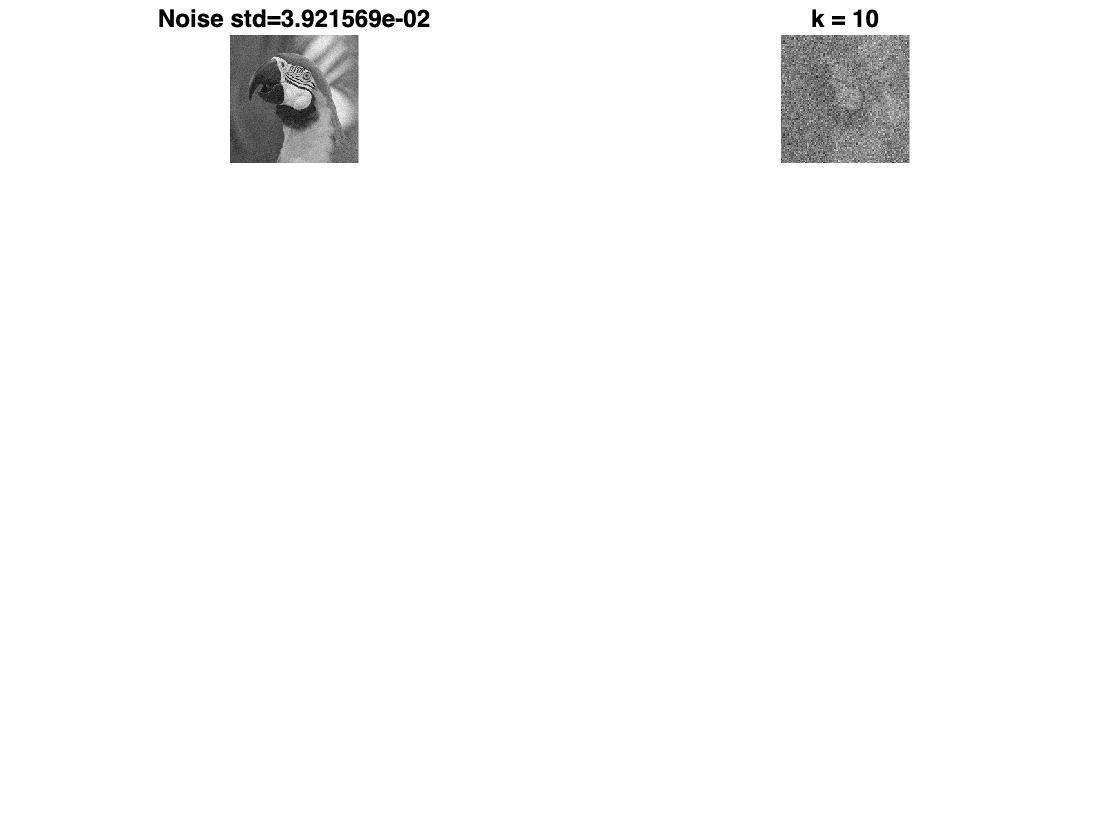

clear; close all; clc;
g = im2double(imread('Ex1/parrot.png'));
g = im2gray(g);

noise_levels = [10];
k_values = [10];
dt = 1;
lambda = 0.1;   % no fidelity term in (b)

T = 5;
iter = round(T/dt);
figure;
tiledlayout(5,2,"TileSpacing","tight","Padding","tight");
for ni = 1:length(noise_levels)
    sigma = noise_levels(ni)/255; %0-1

    f = g + sigma * randn(size(g));

    for ki = 1:length(k_values)
        kpm = k_values(ki);

        [u,~,~] = diffusionPM(f,f,g,iter,dt,lambda,kpm);

       %nexttile; imshow(I,[]); title('Original');
       nexttile; imshow(f,[]); title(sprintf('Noise std=%d',sigma));
       nexttile; imshow(u,[]); title(sprintf('k = %d',kpm));
       
        %sgtitle(sprintf('std=%d, k=%d',sigma,kpm));
    end
end


function [u,mean_vals,std_vals,SNR] = diffusionPM(f,u,g,iter,dt,lamda,kpm)
mean_vals = zeros(1,iter);
std_vals = zeros(1,iter);
SNR = zeros(1,iter);

for i=1:iter
[ux,uy] = grad(u);
ax = ux./(1+((abs(ux)/kpm)^2));
ay = uy./(1+((abs(uy)/kpm)^2));
u_t = div(ax,ay);
fidelity_t = f-u;
u = u+dt.*(u_t+lamda*fidelity_t);
mean_vals(i)=mean(u(:));
std_vals(i)=std(u(:));
SNR(ki) = 20*log10( norm(g(:)) / norm(g(:)-u(:)) );
end

end



%in images we assume h=1
function [fx,fy] = grad(V)
%forward difference gradient
fx = V(:,[2:end,end])-V;%select all rows, and shift cols +1 right, and duplicate last col again so we get direlhe boundry of 0
fy = V([2:end,end],:)-V;
end

function bd = div(Vx,Vy)
%backward difference divergence
fx = Vx - Vx(:,[1,1:end-1]); fx(:,1)=Vx(:,1); fx(:,end)=-Vx(:,end-1);
fy = Vy - Vy([1,1:end-1],:); fy(1,:)=Vy(1,:); fy(end,:)=-Vy(end-1,:);
bd = fx + fy;
end



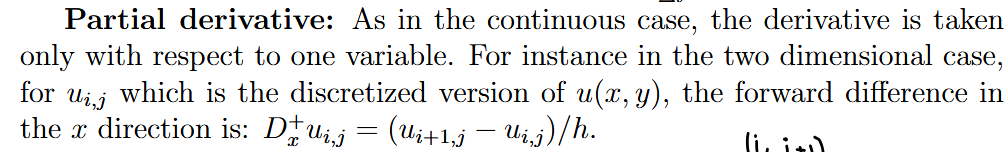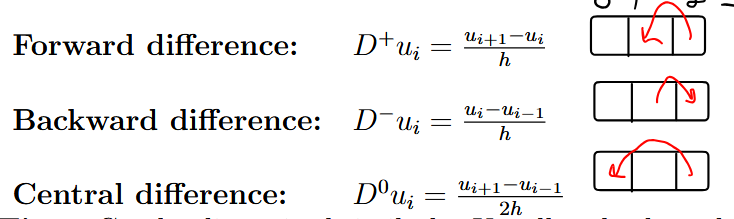

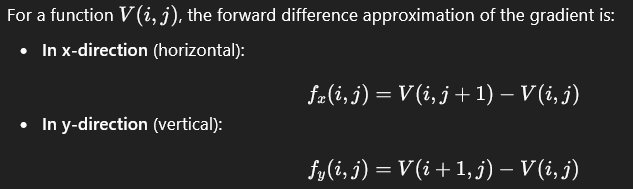

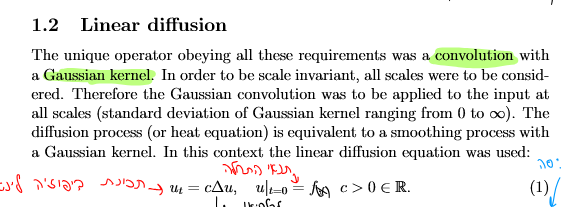

function img = loadImageFromSubfolder(subfolder, filename)
%LOADIMAGEFROMSUBFOLDER Load image from a subfolder relative to this .m file.
%
%   img = loadImageFromSubfolder(subfolder, filename)
%
%   Example:
%       img = loadImageFromSubfolder('images', 'cat.png');

    % Get the folder of the caller .m file
    baseFolder = fileparts(mfilename('fullpath'));

    % Construct full path to the subfolder
    targetFolder = fullfile(baseFolder, subfolder);

    % Construct full path to the image file
    imgPath = fullfile(targetFolder, filename);

    % Check if the file exists
    if ~isfile(imgPath)
        error('File not found: %s', imgPath);
    end

    % Read the image
    img = imread(imgPath);
end
